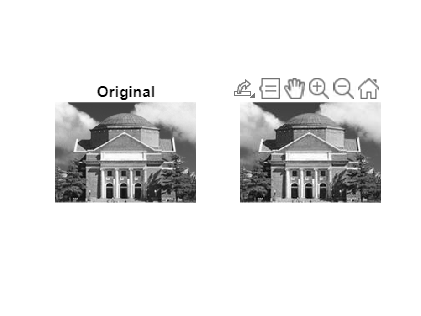

clear
clc

load('hall.mat');
[ACstream, DCstream, h, w] = JpegEncoderHalfStep(hall_gray);
Image_Decoded = JpegDecoderHalfStep(DCstream,ACstream,h,w);
subplot(1,2,1);
imshow(hall_gray);
title('Original');
subplot(1,2,2);
imshow(Image_Decoded);
title('Compressed');

肉眼观察差别不大

计算PSNR

MSE = sum((Image_Decoded-hall_gray).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

PSNR = 37.2983，比标准步长的34.8926更高，失真更小，但提升不大

计算压缩比

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

compressrate = 4.4097，压缩比比标准步长之下的6.4247明显更小

这说明实际使用中选用更小的量化步长可能对失真的抑制效果有限，但却严重牺牲了压缩性能

function Image = JpegDecoderHalfStep(DCstream,ACstream,img_h,img_w)
    blockamountW = ceil(img_w/8);
    blockamountH = ceil(img_h/8);
    blockamount = blockamountH * blockamountW;
    DCarray = DCdecoder(DCstream,blockamount);
    ACarray = ACdecoder(ACstream,blockamount);
    arrayFull = [DCarray;ACarray];
    iZigzagMtx = zeros(blockamountH,blockamountW);
    for y = 1:blockamountH
        startY = (y-1) * 8 + 1;
        for x = 1:blockamountW
            startX = (x-1) * 8 + 1;
            iZigzagMtx(startY:startY + 7,startX:startX + 7) = i_zigzag88_scan(arrayFull(:,(y-1) * blockamountW + x));
        end
    end
    load('JpegCoeff.mat','QTAB');
    QTAB = QTAB/2;
    deRoundMat = blockproc(iZigzagMtx,[8 8],@(mat)(round(mat.data.*QTAB)));
    iDCTmtx = blockproc(deRoundMat,[8 8],@(mat)(idct2(mat.data)));
    Image = uint8(iDCTmtx + 128);
end


function [ACstream,DCstream,imgH,imgW] = JpegEncoderHalfStep(inMat)
    [imgH, imgW] = size(inMat,[1 2]);
    load('JpegCoeff.mat','ACTAB','DCTAB','QTAB');
    QTAB = QTAB/2;
    dctMat = blockproc(double(inMat) - 128,[8 8],@(mat)(dct2(mat.data)));
    roundMat = blockproc(dctMat,[8 8],@(mat)(round(mat.data./QTAB)));
    zigzagMat = blockproc(roundMat,[8 8],@(mat)(zigzag88_scan(mat.data)));
    [h, w] = size(zigzagMat,[1 2]);
    rslt = [];
    for i = 1:h % row1(col1 2 3 ......) row2 ......
        for j = 1:64:w
            rslt = [rslt,zigzagMat(i,j:j+63)'];
        end
    end
    DCarray = rslt(1,:);
    ACarray = rslt(2:end,:);

    % generate DC stream
    DCdiff = [2*DCarray(1),DCarray(1:end-1)] - DCarray; % diff
    DCcat = ceil(log2(abs(DCdiff)+1)); %calculate DC category
    DCstream = [];
    for i = 1:length(DCcat)
        lenHuffman = DCTAB(DCcat(i)+1,1);
        if DCcat(i) ~= 0
            binTemp = dec2bin(abs(DCdiff(i))) - '0';
            if DCdiff(i)<0
                binTemp = ~binTemp;
            end
        else
            binTemp = [];
        end
        DCstream = [DCstream,DCTAB(DCcat(i)+1,2:(1+lenHuffman)),binTemp];
    end

    % generate AC stream
    ACstream = [];
    for j = 1:length(DCarray)
        
        zeroCount = 0;
        for i = 1:63
            ACnum = ACarray(i,j);
            if ACnum ~= 0
                ZRLcount = floor(zeroCount/16); % how many ZRLs should be added
                Run = mod(zeroCount,16); %run
                Size = ceil(log2(abs(ACnum)+1)); %size
                if(ACnum > 0)
                    Amp = dec2bin(ACnum)-'0';
                else
                    Amp = ~(dec2bin(-ACnum)-'0');
                end % Amplitude
                ACTABidx = Run*10 + Size;
                ACstream = [ACstream,repmat([1,1,1,1,1,1,1,1,0,0,1],[1,ZRLcount]),...
                            ACTAB(ACTABidx,4:(3+ACTAB(ACTABidx,3))),Amp];
                zeroCount = 0;
            else
                zeroCount = zeroCount + 1;
            end
        end
        ACstream = [ACstream,[1,0,1,0]];
    end
end